# **Température de flamme **

## **1.Températures de Flamme : principe**

On s'intéresse aux température de flamme des quatre gaz suivants :

- acéthylène,

- butane,

- méthane,

- propane,

Pour cela on considère leur réaction de combustion, soit sous oxygène pure soit sous air. On va considérer que les réactions sont adiabatiques, et on vérifiera cette hypothèses à partir de données expérimentales de températures de flamme. Comme les températures sont très élevées, il est indispensable de tenir compte de l'évolution avec la température des capacités thermiques des gas présents après la combustion, $C_p(t)$.

Rappel des réactions de combustion de ces gas avec les enthalpies de combustion : 

- acétylène : $\mathrm{C_2H_{2 (g)}+\frac{5}{2}O_2\rightarrow 2CO_{2 (g)}+H_2O_{ (g)}}$   $\Delta _{c,a} \bar H_{298}^0=-1256\, \mathrm{kJ\cdot mol^{-1}}$

- butane : $\mathrm{C_4H_{10 (g)}+\frac{13}{2}O_2\rightarrow 4CO_{2 (g)}+5H_2O_{ (g)}}$      $\Delta _{c,b} \bar H_{298}^0=-2044\, \mathrm{kJ\cdot mol^{-1}}$

- méthane  : $\mathrm{CH_{4 (g)}+2O_2\rightarrow CO_{2 (g)}+2H_2O_{ (g)}}$      $\Delta _{c,m} \bar H_{298}^0=-803\, \mathrm{kJ\cdot mol^{-1}}$

- propane : $\mathrm{C_3H_{8 (g)}+5O_2\rightarrow 3CO_{2 (g)}+4H_2O_{ (g)}}$      $\Delta _{c,p} \bar H_{298}^0=-2044\, \mathrm{kJ\cdot mol^{-1}}$

Calcul de la température de flamme :

On considère que la réaction opère à pression constante, et qu'elle est adiabatique. La chaleur de réaction est utilisée pour élever la température des gaz, jusqu'à la température de flamme. Ce qui s'écrit : 

    
$$\Delta_r\bar H_{298}^o+\int_{298}^{Tf}(\Sigma n_iC_{p,i}(T)) dT=0$$


Lorsque les $C_p$ sont indépendants de la température, l'équation est très simple, mais lorsqu'on prend en compte les dépendances avec la température des $C_p$, l'équation peut devenir imposible à résoudre analytiquement, selon les formes des $C_p(T)$. Nous allons donc chercher une solution numérique.

## 2. Détermination des Cp

Nous allons chercher les évolutions de $Cp$ avec la teméprature. Pour cela, on considère le site [https://www.engineeringtoolbox.com](https://www.engineeringtoolbox.com) qui propose des données sous forme tabulée. Pour les utiliser, il faut donc (i) importer ces données, puis (ii) les traiter pour pouvoir les utiliser sous une forme de fonction $C_p(T)$.

Pour cela, nous allons partir d'un fichier texte ou Excel dans lesquels les données auront cette allure :

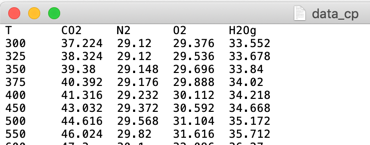           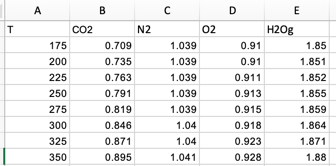

### 2.1 Importation des données

Pour informations des données tabulées peuvent être importées dans Matlab de plusieurs manières :   

- en "collant" des données depuis le presse papier directement dans Matlab.

- en important un fichier manuellement en utilisant l'outils dédié dans Matlab.

- en importat un fichier directement à partir d'une ligne de commande.

La première méthode est la plus rapide et la plus simple lorsqu'on le fait une seule fois, la dernière étant la plus efficace lorsque on doit répétéer ce type de manip.

#### (a) Coller depuis le presse papier

Il suffit de cliquer dans la fenêtre "workspace" de Matlab sur le petit triangle, ce qui ouvre un masque d'import de données (cf figure), et de se laisser guider. Si par exemple on a collé deux colonnes des données $T$ et $C_p$ on peut leur donner les noms T et Cp_O2 et choisir dans "Output type" "column vectors", si l'on veut importer chaque liste de quantité dans une variable individuelle (cf ci-dessous)

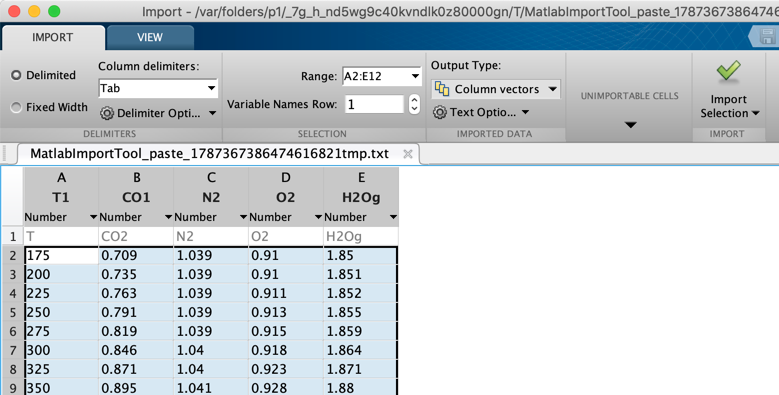

Il peut également être pratique d'importer les données dans une variable de type "table", ce qui permet de mélanger les titres dans la première ligne et les données dans les autres. Cela permet notamment d'explorer les valeurs ou de les vérifier, avant de transférer les données dans desvecteurs colonnes individuels. 

#### (b) Import de fichier manuellement

 En important directement les données depuis un fichier texte, depuis un fichier excel. On peut utiliser l'utilitaire d'import de fichier.

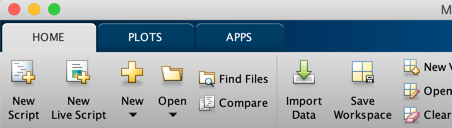

L'outil est accessible par l'icone "import Data" dans l'onglet "HOME" de la fenètre principale de Matlab. Là encore il suffit de se laisser guider en cliquant sur le fichier. On se retrouve ensuite dans la même fenêtre d'importation que dans le cas (b) précédent.

#### (c) Import de fichier par ligne de commande

 L'import de données depuis un **fichier texte** par ligne de commande est très simple, notamment si on passe par la création d'une table dans Matlab. Supposant que les données sont dans un fichier texte, par exemple "data_cp.txt" avec les mêmes cinq colonnes et dont les données seraient séparées par des tabulations comme séparateurs, et en supposant que la première ligne contienne les titres :

il est possible et pratique d'importer l'ensemble des données dans une variable Matlab de type "Table" qui permet de mixer des données de types différents, en utilisant la fonction :

Dans l'exemple ci-dessus, le fichier était dans le répertoir de travail de Matlab, ce qui est le plus simple, mais dans le cas contraire, il faudra ajouter le chemin du fichier devant le nom. On notera que si les données du fichier sont limitées par un autre séparateur, par exemple une virgule, il suffit de remplacer la variable "délimiter". 

Dans le cas d'un fichier excel qui aurait le même nom, qui pourrait comporter plusieurs feuilles dont celle contenant les données s'appellerait 'Cp_val' et serait dans les colonnes B1:F48, la fonction serait :

Evidemment si le classeur ne contient qu'une feuille avec seulement les données que l'on cherche, les paramètre 'sheet' et 'range' sont inutiles.

#### Transformations des variables "tables" en "arrays"

Si les données ont été importées directement dans des "arrays" (qui ne comportent que des nombres) on peut les utiliser directement pour les analyser. Par contre, si on a importé l'ensemble des données dans une variable de type "table", il peut être pratique à partir du code de les transformer en "arrays", par exemple 5 vecteurs contenant les températures et 4 autres contenant les valeurs des $C_p$.  Par exemple pour la variable température la commande est :

on affecte les données des lignes 2 à 47 de la colonne 1.

#### Exemple d'application du code

On exécute le cole chargeant le fichier texte et en affcetant les séries de données à 5 variables et en transformant les unités initialement en kJ/kg/K en kJ/mol/K, en multipliant par la masse molaire en g.

data_cp = readtable('data_cp_kJKg-1K-1.xlsx','sheet','Cp_val','range','A1:E53');  %place les données dans une table
Temp=table2array(data_cp(:,1));       %Transforme les données depuis une variable "table" en "array" qui ne comprend que des nombres
M_CO2=44; M_N2=28; M_O2=32; M_H2O=18;   % masses molaires
Cp_CO2=table2array(data_cp(:,2))*M_CO2; % tables Cp en kJ/mol/K
Cp_N2=table2array(data_cp(:,3))*M_N2;
Cp_O2=table2array(data_cp(:,4))*M_O2;
Cp_H2O=table2array(data_cp(:,5))*M_H2O;

### 2.2 Utilisation des données :

Pour traduire les tables de données dans des fonctions $C_p(T)$, différentes méthodes peuvent être appliquées : 

(i) Par ajustement des tables de points par une fonction de type polynomiale. Il faut alors veiller  à ce que l'ajustement décrive sufisamment bien le comportement des points expérimentaux dans le domaine de température considérée.

(ii) par une fonction qui va interpoler les valeurs quelconques entre deux points expérimentaux.  Matlab est bien adapté à cette méthode, puisqu'il existent des fonctions permettant de le faire directement.

On va mettre en oeuvre cette dernière méthode particulièrement facile avec Matlab. En effet, il existe une fonction dans Matlab permettant d'interpoler pour toute valeur $x_1$ la valeur $y_1$ à partir de duex vecteurs (lignes ou colonnes) $x$ et $y$. Cette fonction s'écrit :

Le quatrième paramètre précisant la méthode (par défaut 'linear'') est important. En effet, si l'on a peu de points et que l'on choisisse une interpolation linéaire, les résultat sera peu précis. Dans le cas présent, le choix d'une interpolation linéaire est  certainement suffisant puisqu'on dispose d'un grand nombre de valeurs de $C_p$ dans nos tables de départ. 

Le cinquième paramètre permet d'autoriser l'extrapolation des données en dehors de la gamme des valeurs de $x$. En l'absence de valeur pour ce paramètre, si on demande une valeur $x_1$ en dehors de $x$, la fonction retournera le message d'absence de valeur numérique 'NaN'. Dans notre cas cela peut poser des difficultés dans la recherche finale de la température de flamme pour laquelles on va utiliser une fonction de recherche de zéro d'une fonction qui peut être amené à travailler un peu en dehors du domaine. Finalement nous proposons d'écrire la fonction de la façon suivante :

Nous allons donc définir comme dans le cas précédént les fonctions $C_p(T)$ en utilisant cette fonction d'interpolation en utilisant le concept de d' "anynous fonctions" de Matlab.

iCp_CO2=@(T) interp1(Temp,Cp_CO2,T,'linear','extrap') % fonctions Cp(T)

iCp_CO2 = function_handle with value:
    @(T)interp1(Temp,Cp_CO2,T,'linear','extrap')

iCp_N2=@(T) interp1(Temp,Cp_N2,T,'linear','extrap')

iCp_N2 = function_handle with value:
    @(T)interp1(Temp,Cp_N2,T,'linear','extrap')

iCp_O2=@(T) interp1(Temp,Cp_O2,T,'linear','extrap')

iCp_O2 = function_handle with value:
    @(T)interp1(Temp,Cp_O2,T,'linear','extrap')

iCp_H2O=@(T) interp1(Temp,Cp_H2O,T,'linear','extrap')

iCp_H2O = function_handle with value:
    @(T)interp1(Temp,Cp_H2O,T,'linear','extrap')

### 2.3 Vérification des fonctions 

Il est intéressant de tracer les courbes sur les points expérimentaux, en étendant  la plage de températures pour vérifier ce que donnent les extrapolations pour les valeurs $T>6000$.

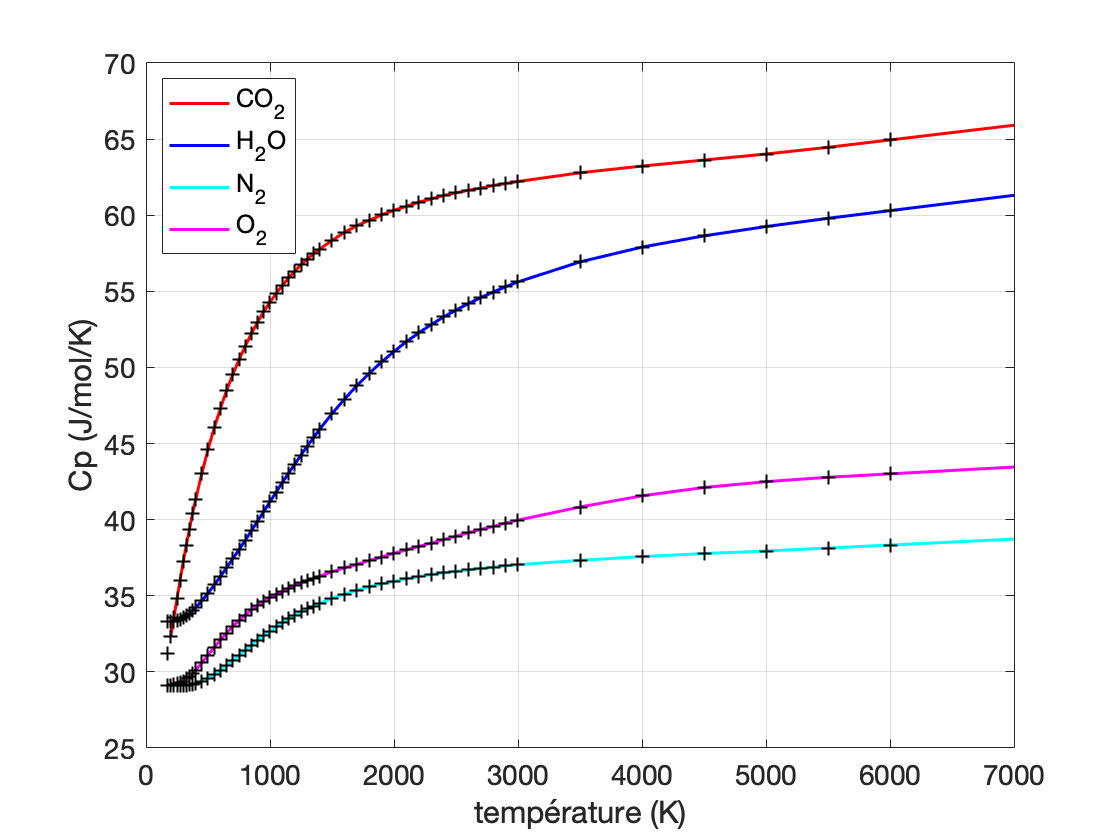

     % tracé des courbes
    Te=200:20:7000;
    plot(Te,iCp_CO2(Te),'color','r','LineWidth',1.5); hold on
    plot(Te,iCp_H2O(Te),'color','b','LineWidth',1.5)
    plot(Te,iCp_N2(Te),'color','c','LineWidth',1.5)
    plot(Te,iCp_O2(Te),'color','m','LineWidth',1.5);
    plot(Temp,Cp_CO2,'k+',Temp,Cp_H2O,'k+',Temp,Cp_N2,'k+',Temp,Cp_O2,'k+');hold off
    grid on
    %set(gca,'XTickLabel',d,'FontName','Helvetica','fontsize',16);
    xlabel('température (K)')
    ylabel('Cp (J/mol/K)')
    legend('CO_2','H_2O','N_2','O_2','location','northwest')
    axe = gca;
    axe.FontSize=14;

On constate que cette méthode donne des résultats meilleurs que la précédente et même l'extrapolation au delà de l'amplitude semble très honnête.

## 3. Calcul des températures de flammes

Nous allons calculer la température de flamme en supposant que la température initiale est $T_0=300\,\mathrm{K}$.

DcaH=-1256;  % acethylène combustion reaction kJ/mol
DcbH=-2653;  % butane in kJ/mol
DcmH=-803;   % methane in kJ/mol
DcpH=-2044;  % propane in kJ/mol
T0=300

T0 = 300

### 3.1 Température de combustion sous air

Il faut déterminer les coefficients stoechiométriques des produits de réactions et des gaz présents après de la combustion. Par exemple, dans le cas de l'acéthylènes, on a : $n_{CO_2}=2$, $n_{H_2O}=1$ et $n_{N_2}=10$. Pour rendre notre calcul plus versatile, nous allons paramétrer, les différentes valeurs de $n$. Ainsi, en changeant simplement les valeurs de $n$ on pourra considérer des réactions sous air, sous oxygène, ou imcomplètes.

Pour résoudre le calcul, on peut le décomposer en écrivant :


$$\Sigma C_p(T)=n_{CO_2}Cp_{CO_2}(T)+n_{H_2O}Cp_{H_2O}(T)+n_{N_2}Cp_{N_2}(T)$$


$integ(T_x)=\int_{T_0}^{T_x} \Sigma(T_x)dT+\Delta_rH$ et l'on cherche à trouver le 0 de cette fonction $integ(T_x)$, ce qui peut s'écrire :

%acethylène :
n_CO2=2; n_H2O=1; n_N2=10;
sig_Cp=@(T) n_CO2*iCp_CO2(T)+n_H2O*iCp_H2O(T)+n_N2*iCp_N2(T);
integ=@(Tx) integral(sig_Cp,T0,Tx)+DcaH*1e3;
Tf_a=fzero(integ,5000); fprintf('Tf_a = %1.0f K',Tf_a)

Tf_a = 2814 K


% butane :
n_CO2=4; n_H2O=5; n_N2=26;
sig_Cp=@(T) n_CO2*iCp_CO2(T)+n_H2O*iCp_H2O(T)+n_N2*iCp_N2(T);
integ=@(Tx) integral(sig_Cp,T0,Tx)+DcbH*1e3;
Tf_b=fzero(integ,5000); fprintf('Tf_b = %1.0f K',Tf_b)

Tf_b = 2324 K


%méthane :
n_CO2=1; n_H2O=2; n_N2=8;
sig_Cp=@(T) n_CO2*iCp_CO2(T)+n_H2O*iCp_H2O(T)+n_N2*iCp_N2(T);
integ=@(Tx) integral(sig_Cp,T0,Tx)+DcmH*1e3;
Tf_m=fzero(integ,5000); fprintf('Tf_m = %1.0f K',Tf_m)

Tf_m = 2260 K


%propane :
n_CO2=3; n_H2O=4; n_N2=20;
sig_Cp=@(T) n_CO2*iCp_CO2(T)+n_H2O*iCp_H2O(T)+n_N2*iCp_N2(T);
integ=@(Tx) integral(sig_Cp,T0,Tx)+DcpH*1e3;
Tf_p=fzero(integ,5000); fprintf('Tf_p = %1.0f K',Tf_p)

Tf_p = 2322 K

Finalement les résultats sont très proches.

### 3.2 Température de combustion sous oxygène.

Le calcul est similaire, seulement les gaz produits sont différents, on peut donc facilement recopier les lignes de code précédentes en les modifiant.

%acethylène :
n_CO2=2; n_H2O=1; n_N2=0;
sig_Cp=@(T) n_CO2*iCp_CO2(T)+n_H2O*iCp_H2O(T)+n_N2*iCp_N2(T);
integ=@(Tx) integral(sig_Cp,T0,Tx)+DcaH*1e3;
Tf_ao=fzero(integ,5000); fprintf('Tf_ao = %1.0f K',Tf_ao)

Tf_ao = 7391 K


% butane :
n_CO2=4; n_H2O=5; n_N2=0;
sig_Cp=@(T) n_CO2*iCp_CO2(T)+n_H2O*iCp_H2O(T)+n_N2*iCp_N2(T);
integ=@(Tx) integral(sig_Cp,T0,Tx)+DcbH*1e3;
Tf_bo=fzero(integ,5000); fprintf('Tf_bo = %1.0f K',Tf_bo)

Tf_bo = 5592 K


%méthane :
n_CO2=1; n_H2O=2; n_N2=0;
sig_Cp=@(T) n_CO2*iCp_CO2(T)+n_H2O*iCp_H2O(T)+n_N2*iCp_N2(T);
integ=@(Tx) integral(sig_Cp,T0,Tx)+DcmH*1e3;
Tf_mo=fzero(integ,5000); fprintf('Tf_mo = %1.0f K',Tf_mo)

Tf_mo = 5222 K


%propane :
n_CO2=3; n_H2O=4; n_N2=0;
sig_Cp=@(T) n_CO2*iCp_CO2(T)+n_H2O*iCp_H2O(T)+n_N2*iCp_N2(T);
integ=@(Tx) integral(sig_Cp,T0,Tx)+DcpH*1e3;
Tf_po=fzero(integ,5000); fprintf('Tf_po = %1.0f K',Tf_po)

Tf_po = 5557 K

Evidemment les températures trouvées sont plus élevées car avec la même quantité de chaleur, on chauffe moins de gaz.

## 4 Comparaison des résultats avec des données expérimentales

Dans la litérature on trouve :

Combustion sous air         Combustion sous oxygène

Aetlylène : $T_f=2100^\circ\mathrm{C}$       $T_f=3100^\circ\mathrm{C}$

Butane :    $T_f=1700^\circ\mathrm{C}$       $T_f=2700^\circ\mathrm{C}$

Méthane :   

Propane :   $T_f=18
00^\circ\mathrm{C}$       $T_f=2800^\circ\mathrm{C}$

L'éccart entre températures calculées et valeurs expérimentales est  plus faible pour les combustions sous air, ce qui signifie que les pertes sont plus faibles et donc que l'hypothèse "adiabatique" est moins irréaliste. Dans le cas des combustions sous oxygène l'hypothèse est très éloignée. Les pertes peuvent provenir de l'énergie de craquage de l'eau à haute température et des pertes par rayonnement (en $T^4$). On peut penser que les pertes par convections soient négigeables par rapport à la vitesse de réaction ?

## 5 Estimation des pertes

On considère l'enthalpie de craquage de l'eau : $\Delta_{craq}H=227\times 10^3\,\mathrm{Jmol^{-1}}$

Estimation de la température de flamme si on ne considère plus adiabatique, mais qu'il y a des pertes : $\Delta_{loss}H$. On part des températures réelles disponibles dans la littérature et on estime une valeur $\Delta_{loss}H$nécessaire pour obtenir la température réelle.

DcraqH=227e3; % énergie craquage de l'eau

%acethylène sous oxygène :
Dloss=-DcaH*0.44; % énergie perdue (en écart à l'hypothèse adiabatique)
Tf_acet=3100+273; % température à atteindre (K)
n_CO2=2; n_H2O=1; n_N2=0;
sig_Cp=@(T) n_CO2*iCp_CO2(T)+n_H2O*iCp_H2O(T)+n_N2*iCp_N2(T);
integ=@(Dloss) integral(sig_Cp,T0,Tf_acet)+DcaH*1e3+DcraqH+Dloss*1e3;
Dlo_oxy=fzero(integ,-DcaH*0.44)

Dlo_oxy = 529.8543


%acethylène sous air :
Dloss=-DcaH*0.10; % énergie perdue (en écart à l'hypothèse adiabatique)
Tf_acet=2100+273; % température à atteindre (K)
n_CO2=2; n_H2O=1; n_N2=10;
sig_Cp=@(T) n_CO2*iCp_CO2(T)+n_H2O*iCp_H2O(T)+n_N2*iCp_N2(T);
integ=@(Dloss) integral(sig_Cp,T0,Tf_acet)+DcaH*1e3+DcraqH+Dloss*1e3;
Dlo_air=fzero(integ,-DcaH*0.10)

Dlo_air = 13.2119